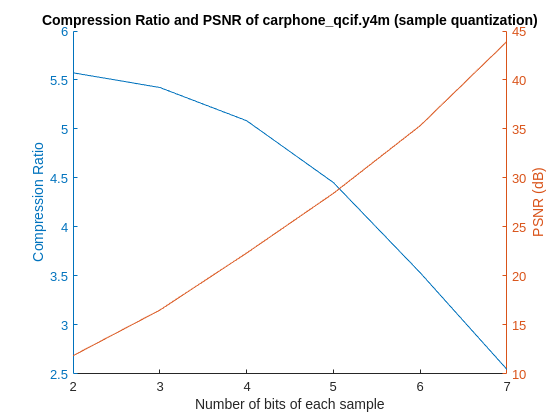

clear;

akiyo_original = 45621044;
bowing_original = 45621044;
carphone_original = 14524448;
city_original = 364957238;
claire_original = 18782912;
football_original = 39538238;

akiyo_frames = 300;
bowing_frames = 300;
carphone_frames = 382;
city_frames = 600;
claire_frames = 494;
football_frames = 260;

x = [7 6 5 4 3 2];
carphone_quant = [43.936377 35.340840 28.434921 22.340733 16.519311 11.865971];
carphone_quant_s = [5704306 4110386 3261403 2856446 2677986 2605880];

carphone_times_enc = [10.388 10.412 10.454 10.221 10.105 10.149];
carphone_times_dec = [0.683 0.544 0.471 0.707 0.530 0.515];

claire_quant = [45.523184 37.227659 29.440957 22.261676 17.759103 12.284504];
claire_quant_s = [4361012 3734752 3485971 3365584 3301323 3302797];

claire_times_enc = [13.512 13.281 13.144 13.268 13.144 13.044];
claire_times_dec = [0.683 0.578 0.632 0.632 0.852 0.625];

cla reset;
hold on;
yyaxis left;
plot(x, carphone_original ./ carphone_quant_s);
xticks(2:7);
title("Compression Ratio and PSNR of carphone\_qcif.y4m (sample quantization)");
xlabel("Number of bits of each sample");
ylabel("Compression Ratio");
yyaxis right;
plot(x, carphone_quant);
ylabel("PSNR (dB)");
hold off;

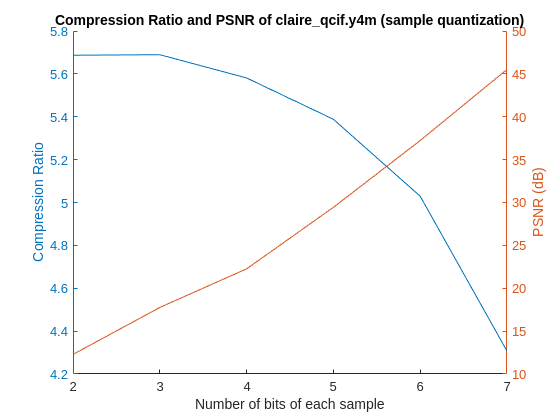


cla reset;
hold on;
yyaxis left;
plot(x, claire_original ./ claire_quant_s);
xticks(2:7);
title("Compression Ratio and PSNR of claire\_qcif.y4m (sample quantization)");
xlabel("Number of bits of each sample");
ylabel("Compression Ratio");
yyaxis right;
plot(x, claire_quant);
ylabel("PSNR (dB)");
hold off;